loading dataset and splitting training and testing sets

y = load('data.csv')';
x = (0:1/199999:1)';
N = size(y,1);
idx = randperm(N);
PD = 0.8;
%splitting the dataset into training and testing sets in 80:20 proportion
x_tr = x(idx(1:round(N*PD)),:);
x_t = x(idx(round(N*PD)+1:end),:);
y_tr1 = y(idx(1:round(N*PD)),:);
y_t1 = y(idx(round(N*PD)+1:end),:);
%normalising x and y
y_tr = (y_tr1-mean(y))./std(y);
y_t = (y_t1-mean(y))./std(y);
x_tr = (x_tr-mean(x))./std(x);
x_t = (x_t-mean(x))./std(x);

m = length(x_tr);
degree = 11;
x2 = [ones(m,1), x_tr, x_tr.^2, x_tr.^3, x_tr.^4, x_tr.^5, x_tr.^6, x_tr.^7,x_tr.^8, x_tr.^9, x_tr.^10, x_tr.^11];
x_test = [ones(length(x_t),1), x_t, x_t.^2, x_t.^3, x_t.^4, x_t.^5, x_t.^6, x_t.^7, x_t.^8, x_t.^9, x_t.^10, x_t.^11];
x1 = normalie(x2);
x_norm_t = normalie(x_test);
%if we want to use the standardisation rather than normalisation we can use
%standar() function created by me for x2.(normalisation was giving better results)
theta1 = zeros(degree+1,1);
iterations = 51500;
alpha = 0.36;

computeCostPol(x1, y_tr, theta1);

%using batch gradient descent to get minimum cost
theta4 = gradientDescentPol(x1, y_tr, theta1, alpha, iterations);

    0.4764

    0.4603

    0.4488

    0.4403

    0.4340

    0.4292

    0.4255

    0.4227

    0.4204

    0.4186

    0.4172

    0.4160

    0.4151

    0.4143

    0.4136

    0.4130

    0.4125

    0.4120

    0.4116

    0.4112

    0.4109

    0.4105

    0.4102

    0.4099

    0.4096

    0.4094

    0.4091

    0.4088

    0.4086

    0.4083

    0.4081

    0.4078

    0.4076

    0.4074

    0.4072

    0.4070

    0.4067

    0.4065

    0.4063

    0.4061

    0.4059

    0.4058

    0.4056

    0.4054

    0.4052

    0.4050

    0.4049

    0.4047

    0.4045

    0.4044

    0.4042

    0.4040

    0.4039

    0.4037

    0.4036

    0.4034

    0.4033

    0.4032

    0.4030

    0.4029

    0.4028

    0.4026

    0.4025

    0.4024

    0.4022

    0.4021

    0.4020

    0.4019

    0.4018

    0.4017

    0.4016

    0.4015

    0.4013

    0.4012

    0.4011

    0.4010

    0.4009

    0.4008

    0.4008

    0.4007

    0.4006

    0.4005

    0.4004

    

% Stochastic gradient descent can also be used but the dataset was not so
% big, so was able to get good results with batch gradient descent

% theta4 = StochasticGradientDescent(x1,y_tr,theta1,alpha,iterations);

%checking goodness of the trained model by calculating mse and coffiecient
%of determination
y_train_estimated = x1*theta4;
yav_tr = mean(y_tr);
sse_tr = sum((y_tr-y_train_estimated).^2);
sst_tr = sum((y_tr-yav_tr).^2);
R2_tr = 100*(1-(sse_tr/sst_tr));
y_test_estimated = x_norm_t*theta4;
yav_t = mean(y_t);
sse_t = sum((y_t-y_test_estimated).^2);
sst_t = sum((y_t-yav_t).^2);
R2_t = 100*(1-(sse_t/sst_t));

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 7\n\t alpha: 0.54',R2_tr, sse_tr/length(y_tr));

training R2: 79.675250 percent
	mse:0.203286
	degree: 7
	 alpha: 0.54

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 7\n\t alpha: 0.54 ',R2_t, sse_t/length(y_t));

testing R2: 79.721957 percent
	mse:0.202621
	degree: 7
	 alpha: 0.54 

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 8\n\t alpha: ',R2_tr, sse_tr/length(y_tr));

training R2: 98.054202 percent
	mse:0.019465
	degree: 8
	 alpha: 

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 8\n\t alpha: ',R2_t, sse_t/length(y_t));

testing R2: 98.005991 percent
	mse:0.019911
	degree: 8
	 alpha: 

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 9\n\t alpha: 0.43',R2_tr, sse_tr/length(y_tr));

training R2: 97.303698 percent
	mse:0.026960
	degree: 9
	 alpha: 0.43

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 9\n\t alpha: 0.43',R2_t, sse_t/length(y_t));

testing R2: 97.252574 percent
	mse:0.027486
	degree: 9
	 alpha: 0.43

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 12\n\t alpha:0.35 ',R2_tr, sse_tr/length(y_tr));

training R2: 96.208285 percent
	mse:0.037866
	degree: 12
	 alpha:0.35 

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 12\n\t alpha:0.35',R2_t, sse_t/length(y_t));

testing R2: 96.166803 percent
	mse:0.038539
	degree: 12
	 alpha:0.35

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 10\n\talpha:0.42',R2_tr, sse_tr/length(y_tr));

training R2: 97.153355 percent
	mse:0.028412
	degree: 10
	alpha:0.42

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 10\n\talpha:0.42',R2_t, sse_t/length(y_t));

testing R2: 97.134110 percent
	mse:0.028877
	degree: 10
	alpha:0.42

fprintf('training R2: %f percent\n\tmse:%f\n\tdegree: 11\n\t alpha: 0.36',R2_tr, sse_tr/length(y_tr));

training R2: 97.519929 percent
	mse:0.024780
	degree: 11
	 alpha: 0.36

fprintf('testing R2: %f percent\n\tmse:%f\n\tdegree: 11\n\t alpha: 0.36',R2_t, sse_t/length(y_t));

testing R2: 97.522333 percent
	mse:0.024859
	degree: 11
	 alpha: 0.36

%after runnning the code multiple times i was able to get best results at
%degree 11. At degree 8, R2training is highest but R2test is much less as
%compared to R2training, which tells us that model has memorized the
%dataset but cannot predict from unknown values. Whereas at degree 11,
%R2test is higher than R2 training, so model has learned from dataset and
%will be able to predict unknown values.
final_theta = theta4; %theta at degree 11
%taking input for prediction and processing it like x set
unknown_number = input("enter the unknown x = ");
u_nor = (unknown_number-mean(x))./std(x);
u1 = [ones(1,1), u_nor, u_nor.^2, u_nor.^3, u_nor.^4, u_nor.^5, u_nor.^6, u_nor.^7,u_nor.^8, u_nor.^9, u_nor.^10, u_nor.^11];
disp(u1);

  Columns 1 through 11

    1.0000    0.1732    0.0300    0.0052    0.0009    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000

  Column 12

    0.0000



ux = zeros(1,12);
ux(1,1) = ones(1,1);
for i=2:size(ux,2)  %as column one is constant 1 no std therefore will reach infinity
    mu = mean(x2(:,i));
    sigma = std(x2(:,i));
    ux(:,i) = (u1(:,i)-mu)./sigma;
end
answer = ux*final_theta;
disp(ux);

  Columns 1 through 11

    1.0000    0.1724   -1.0874    0.0028   -0.7515    0.0006   -0.6025    0.0008   -0.5168    0.0010   -0.4596

  Column 12

    0.0011



disp(answer*std(y)+mean(y));

    1.9723



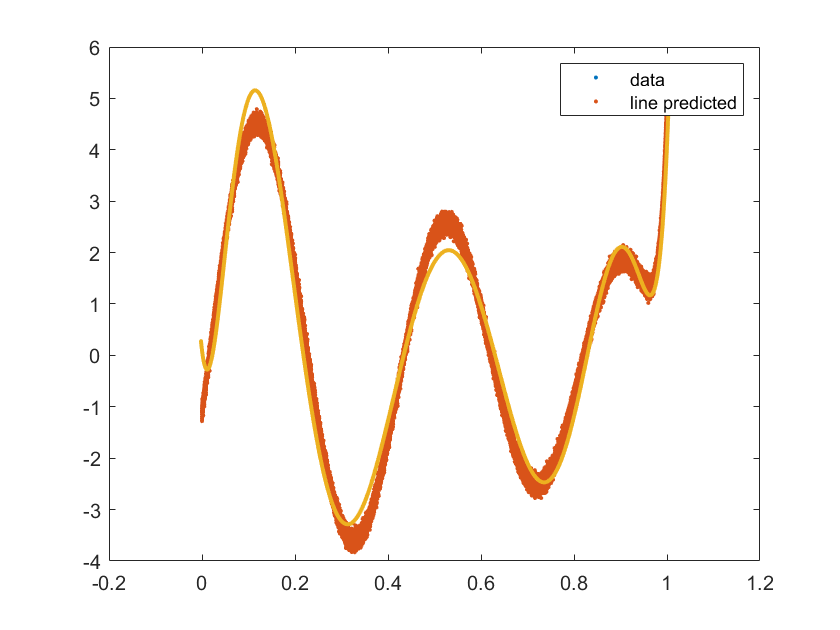

%plotting the equation obtained by weights predicted so far
hold on;
plot(x,y, '.',"LineWidth",2);
plot(x_norm_t(:,2)*std(x)+mean(x), (x_norm_t*final_theta)*std(y)+mean(y), '.',"LineWidth",2);
legend("data", "line predicted");
hold off;